# Lab 9 Radio Havana

### ### Charles Lo ###

## Item 0: Load Workspace 

close all
clear

load short_wave.mat

N = length(x_IQ);

## Item 1: Plot Spectrum of Down-converted Signal

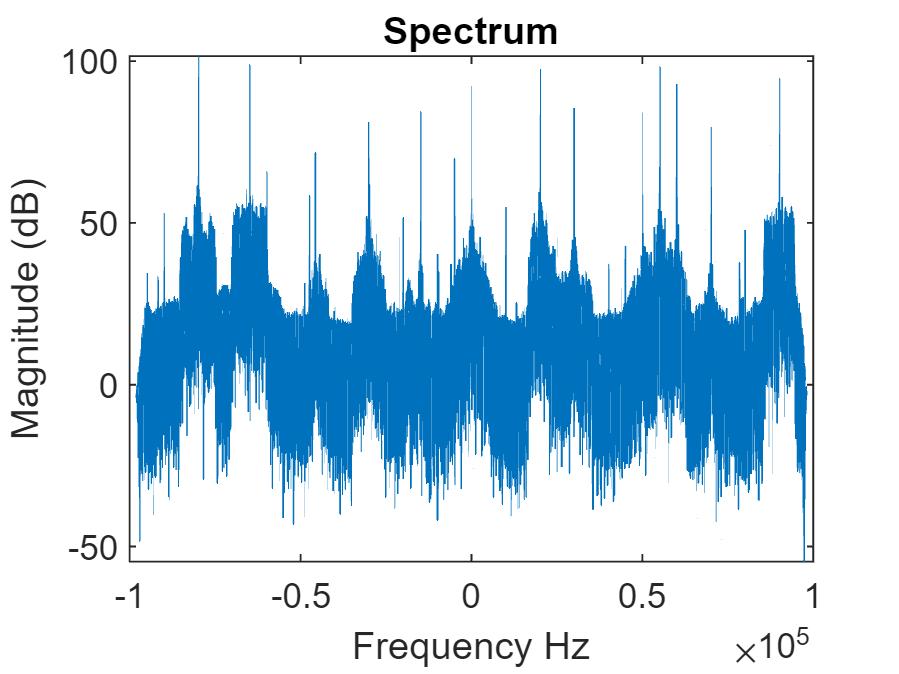

X_IQ = abs(fftshift(fft(x_IQ)));

freq_x = [-(N-1)/2:(N-1)/2]*Fs/N; % DFT frequencies in continous time

plot(freq_x, 20*log10(X_IQ))
xlabel('Frequency Hz')  % <-- Axis label
ylabel('Magnitude (dB)') % <-- Axis label
title('Spectrum') % <-- graph title


bruh = X_IQ

bruh = 1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


## Item 3: Find DFT indices for the Carrier Frequency and Tolerance

% find exact carrier frequency
fc = 0; % Hz
tol = 1000; % Hz

% Complete the following lines of code and uncomment to run

% Calculate ind_c and ind_tol in terms of fc and tol 
    % Hint: Make sure you understand how ind_c and ind_tol are used in
    % getPeak.m
 ind_c = 2097152;  % <-- Index corresponding to fc (integer)
 ind_tol = 1000;  % <-- Index corresponding to tol (integer)


ind_i = getPeak(X_IQ, ind_c, ind_tol);  % Make sure you have this function in the workspace
f_i = freq_x(ind_i);  %frequency corresponding to peak index



## Item 4: Demodulate Radio Havana

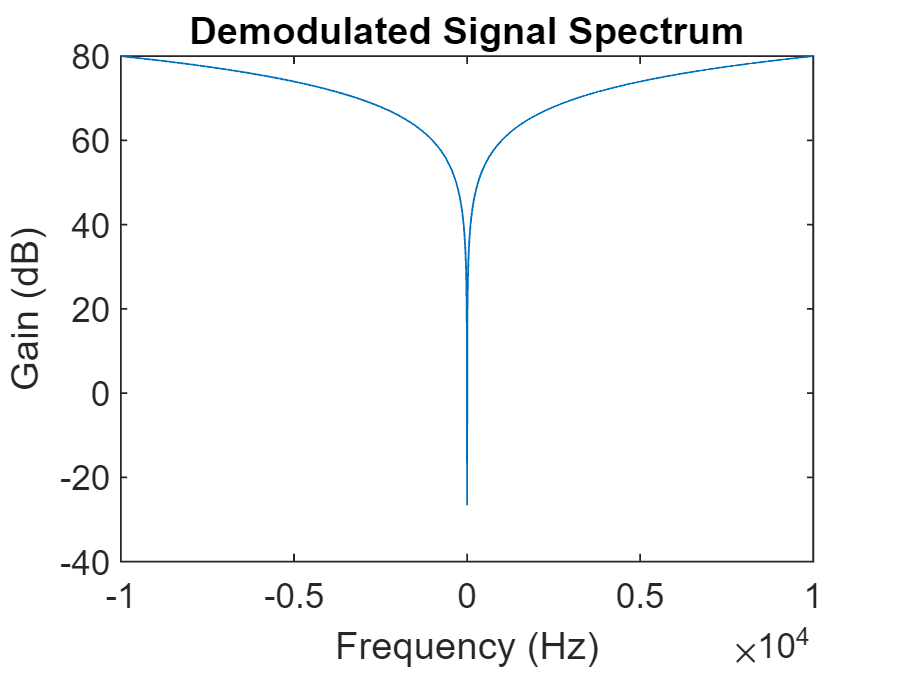

% Demodulate message to account for inexact carrier frequency

% Complete the following line of code and uncomment to run
 s = exp(-j*2*pi*freq_x*f_i/1000); % <--- complex sinusoid corresponding to exact carrier
x_b = real(x_IQ.*s);

% Complete the following line of code and uncomment to run
 a = filter(h,1,x_b);  % <--- apply lowpass filter

% Play demodulated signal
soundsc(a,Fs)


% Plot Demodulated Signal Spectrum

% Complete the following lines of code and uncomment to run
 figure
 plot(freq_x, 20*log10(abs(freq_x)));
 xlabel('Frequency (Hz)')
 ylabel('Gain (dB)')
 title('Demodulated Signal Spectrum')
 xlim([-10000,10000])

## Item 5: Plot Frequency Response of Final Low Pass Filter

**Note**: The following plot will be used for the corresponding Lab Assignment

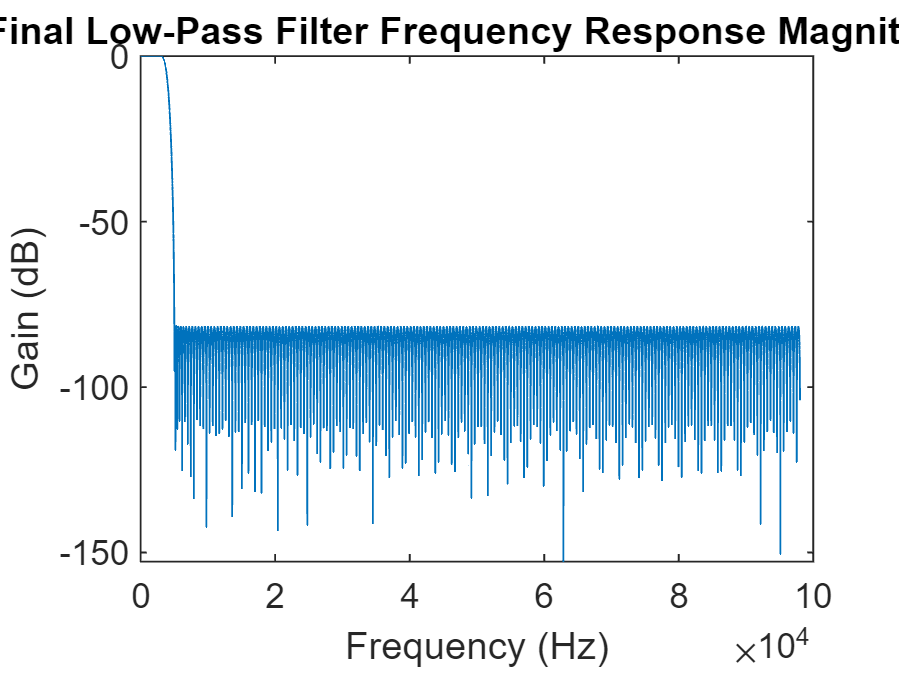

[H,freq_h] = freqz(h,1,8192,Fs);

figure
plot(freq_h,20*log10(abs(H)))
xlabel('Frequency (Hz)')
ylabel('Gain (dB)')
title('Final Low-Pass Filter Frequency Response Magnitude')